# Tutorial: The Individual class

The `Individual` class is the most important class in a modelling exercise with the Computational Physiology Toolbox. It allows to store information on experimental data or for a simulation or estimation task. In this tutorial, you will learn about the structure of this class.

An individual object consists of a number of building blocks. Structure and use of these building blocks are explained in detail in other tutorials. Depending on whether the individual object contains experimental data or a virtual individual, different of these blocks are active:

- observation, dosing, and physiology for experimental data,

- sampling, dosing, physiology, drugdata and model for virtual individuals.

#### Allocating `Individual` objects

To define an `Individual` object, you first have to construct it using function `Individual()`:

A scalar individual which is neither experimental nor virtual yet:

Individual()

ans =   Individual with properties:

           type: []
           name: []
         dosing: [1×1 EmptyDosing]
       drugdata: [1×1 DrugData]
     physiology: [1×1 Physiology]
    observation: []
       sampling: []
          model: []
          estim: []


A virtual individual:

Individual('Virtual')

ans = 	Individual object:

          type: 'Virtual individual'
          name: []
        dosing: '0 dosing events'
    physiology: '0 parameters defined'
      drugdata: '0 parameters defined'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

An individual for experimental data:

Individual('Experimental')

ans = 	Individual object:

          type: 'Experimental data'
          name: []
        dosing: '0 dosing events'
    physiology: '0 parameters defined'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

You can also create arrays of individuals. Here's an array of two experimental individuals

expids = Individual('Experimental',2)

expids = 	Individual array:

1	Experimental data
2	Experimental data

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

and another one of three virtual individuals

simids = Individual('Virtual',3)

simids = 	Individual array:

1	Virtual individual
2	Virtual individual
3	Virtual individual

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

and we can put all these into a single object which contains five individuals, two experimental and three virtual:

ids = [expids; simids]

ids = 	Individual array:

1	Experimental data
2	Experimental data
3	Virtual individual
4	Virtual individual
5	Virtual individual

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

#### Working with Individual objects

Now let's consider two non-empty individuals, one experimental and one virtual. Let's take the Warfarin data from tutorial "importing experimental data"

data = ImportableData('data/Warfarin_Holford1986.csv','Delimiter',',');
data.maprow('Species','Covariate');
data.maprow('Warfarin oral dose','Oral dosing','Compound','Warfarin');
data.maprow('Warfarin plasma concentration','Record','Site','pla');
expid = import(data);

1 experimental dataset(s) imported successfully.


expid.name = 'Warfarin data';

and the empirical PK model from tutorial "Script-level information for models"

obs = PBPKobservables;

simid = Individual('Virtual');
simid.name = '1-cmt model (Warfarin)';

simid.dosing     = Oral('Warfarin', 0*u.h, 15*u.mg);
simid.sampling   = Sampling([0 24]*u.h, obs);

simid.model      = empirical1CMT_PLASMA_macroConstants_linearCL;
simid.model.par  = parameters(...
    'V',          10.9*u.L, ...
    'CL',         0.27*u.L/u.h, ...
    'lambda_po',  1.3/u.h, ...
    'F',          1);

We'll print these individuals at the console and see the difference in defined blocks:

expid

expid = 	Individual object:

           type: 'Experimental data'
           name: 'Warfarin data'
         dosing: '1 Oral event(s)'
     physiology: '1 parameters defined'
    observation: '8 records'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

simid

simid = 	Individual object:

          type: 'Virtual individual'
          name: '1-cmt model (Warfarin)'
        dosing: '1 Oral event(s)'
    physiology: '0 parameters defined'
         model: 'empirical1CMT_PLASMA_macroConstants_linearCL (uninitialized)'
      sampling: 'timespan 0 h - 24 h with 11 observables'
      drugdata: '0 parameters defined'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

Still, they can be treated together and interact in different ways. First, we can store the two individuals in an array

indv = [expid;simid];

and initialize and simulate the model:

initialize(indv)
simulate(indv)

The experimental data are simply left unchanged, so it makes no difference whether to first initialize and simulate and then store the two in one array, or to do it the other way round. We can also plot the two individuals jointly:

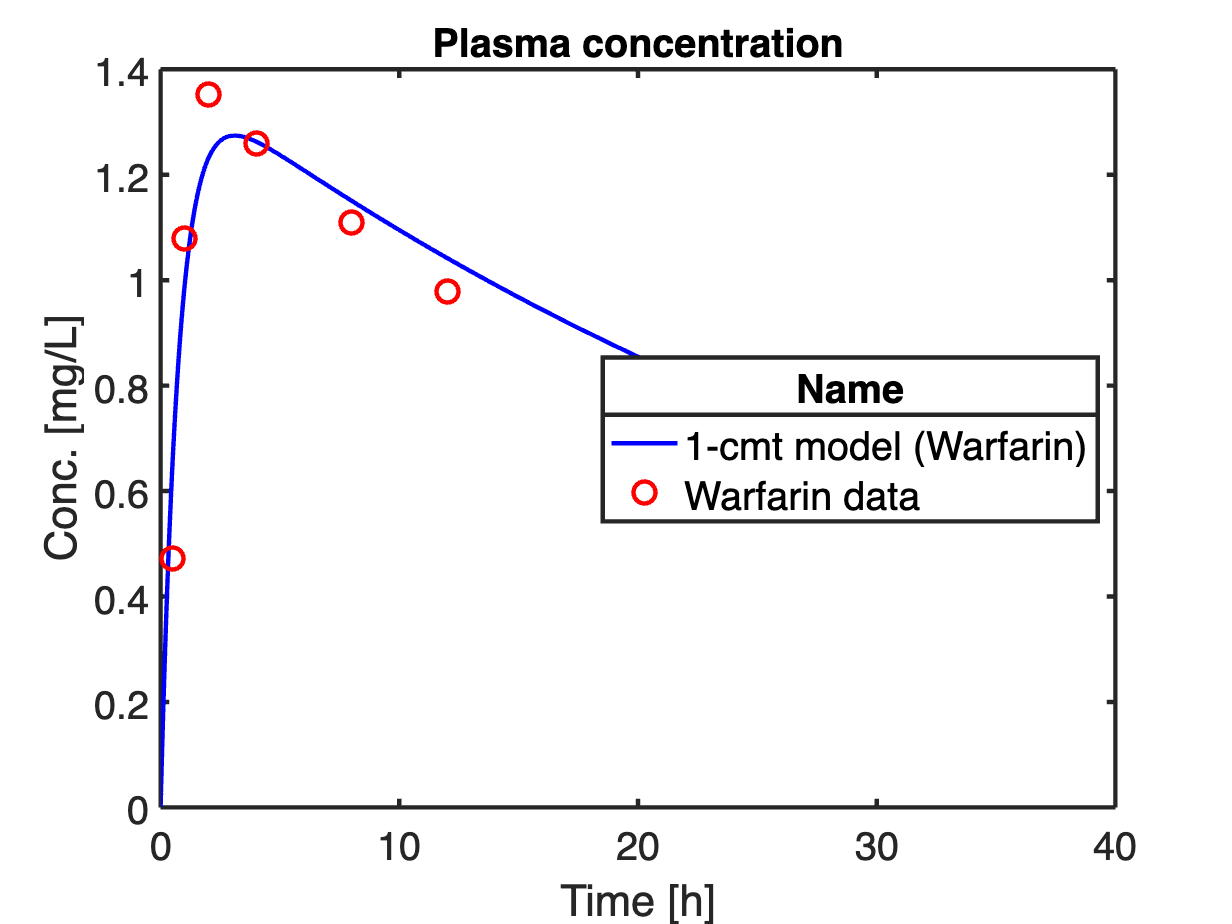

defaultPlots(indv,'plasmaConcentration','yunit','mg/L')

and get the expected output, experimental data as dots, simulation results as lines.

#### Interconversion between virtual and experimental Individual objects

Finally, the structural similarity of the two objects can be exploited. This is done using the interconversion functions `exp2sim()` and `sim2exp()`.

Function `exp2sim()` converts experimental data into a virtual individual. It takes the dosing and physiology block from the experimental individual, together with the sampling schedule extracted from its measurement block. In this way, an almost complete virtual individual is obtained: the only missing part is a model. In this way, you can run a simulation corresponding to the design of the experimental data.

Vice versa, function `sim2exp()` converts a virtual individual into experimental data. The common dosing and physiology block are also left unchanged, and a measurement is obtained from by applying the observation function h to the model output, as specified in the sampling object. This defines a model prediction corresponding to the sampling object, which is taken as the measurement object. In this way, you can a complete set of surrogate experimental data is obtained, like in simulation-reestimation studies.

**Conversion from experimental to virtual:**

In our case, results in a virtual individual with dosing, physiology (here, only the species information), and the 8-row sampling schedule extracted from the experimental data:

exp2sim(expid)

ans = 	Individual object:

           type: 'Virtual individual'
           name: 'Warfarin data'
         dosing: '1 Oral event(s)'
     physiology: '1 parameters defined'
       sampling: 'schedule with 8 observations'
       drugdata: '0 parameters defined'
    observation: '8 records'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

**Conversion from virtual to experimental:**

If we convert `Individual` object `simid`, the doing scheme, physiological parameters (here, none) and observations are extracted:

sim2exp(simid)

ans = 	Individual object:

           type: 'Experimental data'
           name: '1-cmt model (Warfarin)'
         dosing: '1 Oral event(s)'
     physiology: '0 parameters defined'
    observation: '322 records'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ